# Problem 2:

Stem plots of impulse responses for ZOH and linear interpolators are shown in figure 1 and figure 2 respectively.

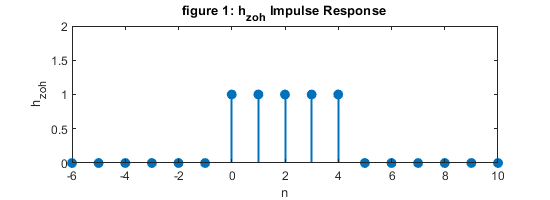

L=5;

hzoh=ones(1,5);

figure
stem(-L-1:2*L,[zeros(1,L+1) hzoh zeros(1,L+1)],'filled','LineWidth',1.5)
ylim([0,2])
xlabel('n')
ylabel('h_z_o_h')
set(gcf,'position',[50,50,550,200])
title('figure 1: h_z_o_h Impulse Response')

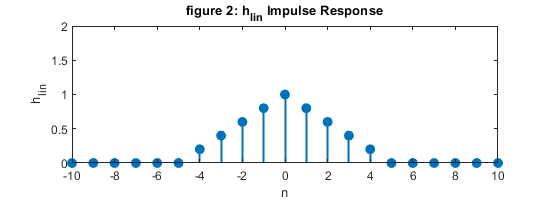

n=-L+1:L-1;
hlin=zeros(1,numel(n));
hlin(abs(n)<=L-1)=1-abs(n(abs(n)<=L-1))/L;

figure
stem(-2*L:2*L,[zeros(1,L+1) hlin zeros(1,L+1)],'filled','LineWidth',1.5)
ylim([0,2])
xlabel('n')
ylabel('h_l_i_n')
set(gcf,'position',[50,50,550,200])
title('figure 2: h_l_i_n Impulse Response')

# Problem 3:

Magnitude plots of frequency responses for ZOH and linear interpolators are shown in figure 3 and figure 4 respectively.

In my opinion, linear interpolation filter is a better approximation to the ideal bandlimited interpolator, because it has smaller magnitude outside of the cutoff frequency.

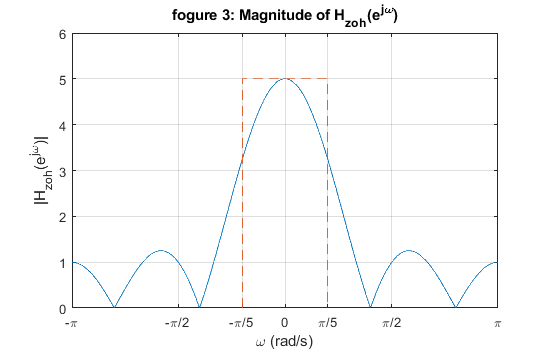

N=1024;
omega=linspace(-pi,pi,N);
Hzoh=fft(hzoh,N);
Mag=abs(Hzoh);
Mag=[fliplr(Mag(1:N/2)) Mag(1:N/2)];

figure,
plot(omega,Mag)
hold on
plot([-pi/L -pi/L pi/L pi/L],[0 L L 0], '--')
xlim([-pi,pi])
grid on
xticks([-pi -pi/2 -pi/5 0 pi/5 pi/2 pi])
set(gca,'XTickLabel',{'-\pi','-\pi/2','-\pi/5','0','\pi/5','\pi/2','\pi'})
xlabel('\omega (rad/s)')
ylabel('|H_z_o_h(e^j^\omega)|')
title('fogure 3: Magnitude of H_z_o_h(e^j^\omega)')
ylim([0,6])
set(gcf,'position',[50,50,550,350])

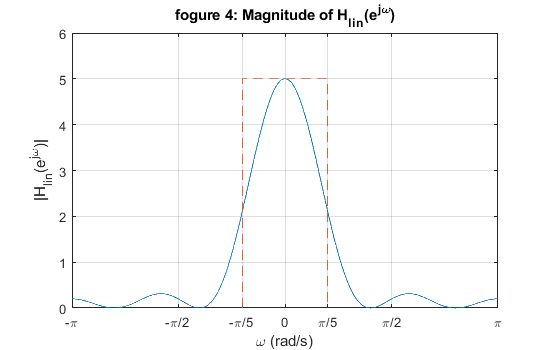

Hlin=fft(hlin,N);
Mag=abs(Hlin);
Mag=[fliplr(Mag(1:N/2)) Mag(1:N/2)];

figure,
plot(omega,Mag)
hold on
plot([-pi/L -pi/L pi/L pi/L],[0 L L 0], '--')
xlim([-pi,pi])
grid on
xticks([-pi -pi/2 -pi/5 0 pi/5 pi/2 pi])
set(gca,'XTickLabel',{'-\pi','-\pi/2','-\pi/5','0','\pi/5','\pi/2','\pi'})
xlabel('\omega (rad/s)')
ylabel('|H_l_i_n(e^j^\omega)|')
title('fogure 4: Magnitude of H_l_i_n(e^j^\omega)')
ylim([0,6])
set(gcf,'position',[50,50,550,350])

# Problem 4:

The following code box, performs the process requested in problem 4.

load('mp1DataFile.mat','data1')

xe=upsample(data1,L);
xzoh=filter(hzoh,1,xe);
xlin=filter(hlin,1,xe);

# Problem 5:

Stem plots of xzoh and xlin are presented in fugure 5 and figure 6, respectively.

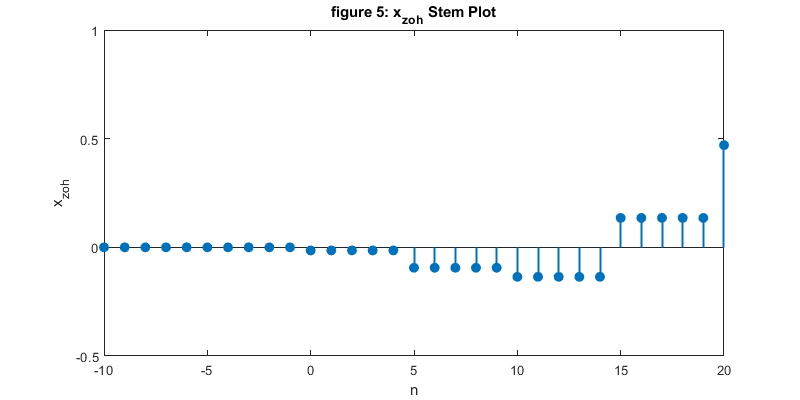

n=-10:20;

figure,
stem(n,[zeros(1,10) xzoh(1:21)],'filled','LineWidth',1.5)
ylim([-0.5,1])
xlabel('n')
ylabel('x_z_o_h')
set(gcf,'position',[50,50,800,400])
title('figure 5: x_z_o_h Stem Plot')

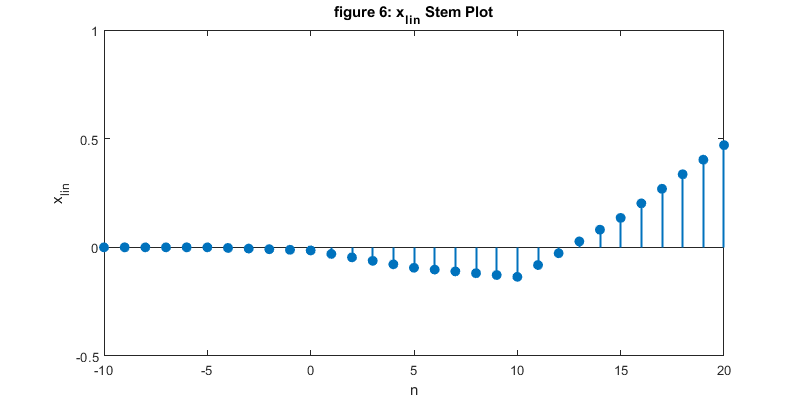

figure,
stem(n,[zeros(1,6) xlin(1:25)],'filled','LineWidth',1.5)
ylim([-0.5,1])
xlabel('n')
ylabel('x_l_i_n')
set(gcf,'position',[50,50,800,400])
title('figure 6: x_l_i_n Stem Plot')

# Problem 6:

Stem plot of hsharp impulse response is illustrated in figure 7.

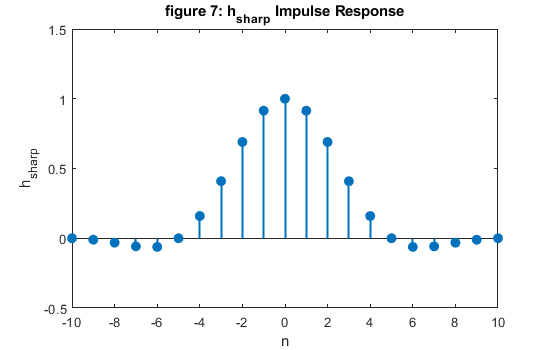

load('mp1DataFile.mat','hsharp')

figure,
stem(-10:10,hsharp,'filled','LineWidth',1.5)
ylim([-0.5,1.5])
xlabel('n')
ylabel('h_s_h_a_r_p')
set(gcf,'position',[50,50,550,350])
title('figure 7: h_s_h_a_r_p Impulse Response')

# Problem 7:

Magnitude of frequency response for hsharp filter is plotted in figure 8. Compared to ZOH and linear interpolation filters, this filter has much smaller magnitudes outside of the cutoff frequency of the ideal interpolation filter. Hence, it seems this is a better approximation to the ideal interpolation filter.

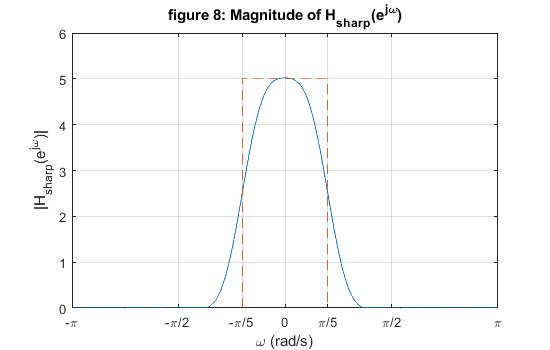

Hsharp=fft(hsharp,N);
Mag=abs(Hsharp);
Mag=[flipud(Mag(1:N/2));Mag(1:N/2)];

figure,
plot(omega,Mag)
hold on
plot([-pi/L -pi/L pi/L pi/L],[0 L L 0], '--')
xlim([-pi,pi])
grid on
xticks([-pi -pi/2 -pi/5 0 pi/5 pi/2 pi])
set(gca,'XTickLabel',{'-\pi','-\pi/2','-\pi/5','0','\pi/5','\pi/2','\pi'})
xlabel('\omega (rad/s)')
ylabel('|H_s_h_a_r_p(e^j^\omega)|')
title('figure 8: Magnitude of H_s_h_a_r_p(e^j^\omega)')
ylim([0,6])
set(gcf,'position',[50,50,550,350])

# Problem 8:

The required stem plot is illustrated in figure 9.

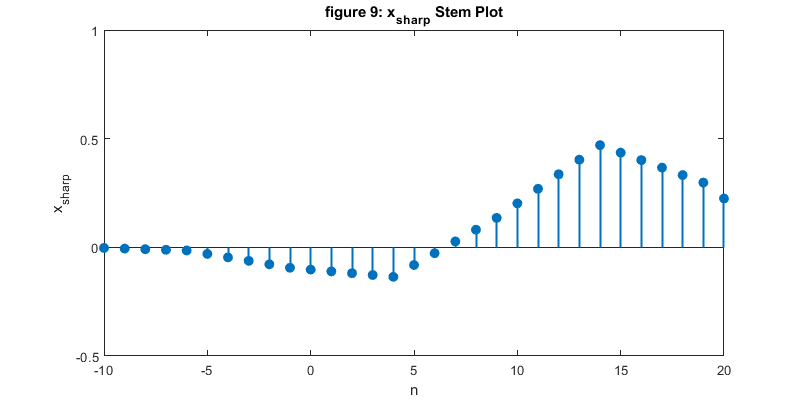

xsharp=filter(hsharp,1,xe);

figure,
stem(n,xlin(1:31),'filled','LineWidth',1.5)
ylim([-0.5,1])
xlabel('n')
ylabel('x_s_h_a_r_p')
set(gcf,'position',[50,50,800,400])
title('figure 9: x_s_h_a_r_p Stem Plot')

# Problem 9:

## a)

In cases that the interpolation impulse response is noncausal, we have to time advance the result of the filter by the amount of the negative time steps in the impulse response. As a result, xzoh will be available for n in range [0,90], xlin will be available for n in range [-4,86], and xsharp will be available for n in range [-10,80].

Difference between conv and filter is that, conv performs a complete convolution and the length of result is length(signal)+length(impulse response)-1. But, the result of filter function has the same length as the input signal.

## b)

The largest interval common to all three filtered outputs is for time step n to be in range [0,80], which is a intersection of ranges from part a.

## c)

The longest transient comes from sharp interpolation filter and the length of it equal to 10. as a result n1=10 , n2=80.

# Problem 10:

load('mp1DataFile.mat','ideal1')

ezoh=mean((xzoh(11:81)-ideal1(11:81)).^2);
elin=mean((xlin(14:84)-ideal1(11:81)).^2);
esharp=mean((xsharp(20:90)-ideal1(11:81)).^2);

disp(['Average interpolation error for ZOH is ', num2str(ezoh)])

Average interpolation error for ZOH is 0.018286


disp(['Average interpolation error for linear interpolation is ', num2str(elin)])

Average interpolation error for linear interpolation is 0.0040771


disp(['Average interpolation error for sharp filter is ', num2str(esharp)])

Average interpolation error for sharp filter is 0.0034131


Among these three options, sharp interpolation filter has the best performance. This conclusion was expected from discussion in problem 7.